We start with denoising. Since its denoising the linear degradation matrix H=I (Identity). 

We first will try on a synthetic noised image. We use the imnoise which creates noise from the image itself. We also have a function getPSNR which computes the PSNR of the estimated image using the original image. 

% Load noise-free image
addpath(genpath('./bm3d'))
imagename = 'cameraman256.png';
org_img = im2double(imread(imagename));
%disp(max(max(org_img)))
amp = 4 ;%amp controlls the noise if amp is higher noise is lower
noise=imnoise(org_img,'poisson')/amp;
disp(max(noise,[],'all'));
y=org_img+noise;
imshow(org_img);
imshow(y);
%disp(rrmse(org_img,y,2));
disp(getPSNR(org_img,y));
y_col = y(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= y(:);
lambda=0.25;

The PSNR of the noisy image is 17.62 . This is since we havent added much noise.We will compare our algorithm performance with performance of a plain gaussian denoiser (BM3D)

Performance of Plain BM3D:

Here we just use the BM3D denoiser. We are using a pre created package for effective implementation of the BM3D algorithm on black-white images.

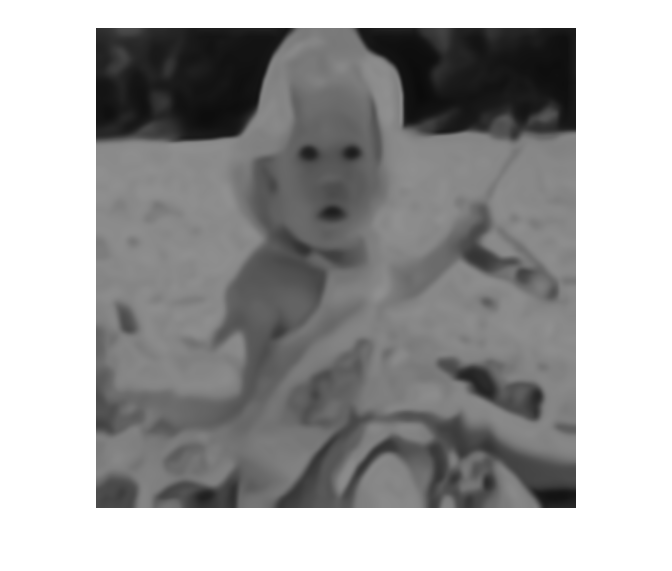

variance= var(noise,0,'all');
% Call BM3D With the default settings.
est = BM3D(y, sqrt(variance));
imshow(est);

%disp(getPSNR(org_img,est));

Arrays have incompatible sizes for this operation.

Error in getPSNR (line 3)
    PSNR = 10*log10(1/mean(mean((y-y_est).^2)));   

Related documentation

%disp(rrmse(org_img,est,2));

The PSNR is quite poor infact lesser than the noised image since BM3D is a gaussian denoiser but here we have poission noise.

beta=200;
epsilon=0.1;
tic
y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
toc

Elapsed time is 28.571365 seconds.


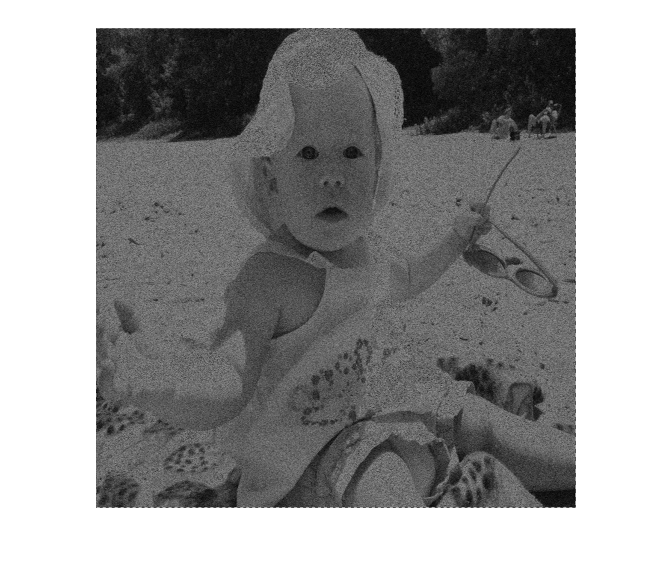

img_est=reshape(y_est,size(org_img));
figure;
imshow(img_est);

%disp(getPSNR(org_img,img_est))
%disp(rrmse(org_img,img_est,2));

Now we perform our algorithm of P4IP. We set lambda to be 0.25 and u to be zero initially since u = x-v and at optimal values u is zero. since we do not know the values of x we assign v as y since the denoised img will be quite similar in values with the noise image and not differ by a very large amount. Note that the weight parameter beta is a hyper parameter which must be tuned. They influence the performance quite a lot. 

First we do a wider search over the values from 10^-5 to 10^4. If beta is very small then its like we are ignoring the gaussian denoiser. Effectively we get the noisy image itself. If the beta value is high its effectively only the BM3D algorithm. So we try to find a opt value.The precision is decided by the epsilon value. We use 1e-1 so that the execution time is faster. 

list=zeros(10,1);
epsilon=1e-1;
for i=1:10
    beta=10^(i-6);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
    temp=reshape(y_est,size(org_img));
    list(i)=getPSNR(org_img,temp);
end

Printing the rrmse while breaking the algo   1.9993e-04

Printing the rrmse while breaking the algo    0.0018

Printing the rrmse while breaking the algo    0.0431

Printing the rrmse while breaking the algo    0.0355

Printing the rrmse while breaking the algo    0.0407

Printing the rrmse while breaking the algo    0.0319

Printing the rrmse while breaking the algo    0.0384

Printing the rrmse while breaking the algo    0.0518

Printing the rrmse while breaking the algo    0.0546

Printing the rrmse while breaking the algo    0.0549



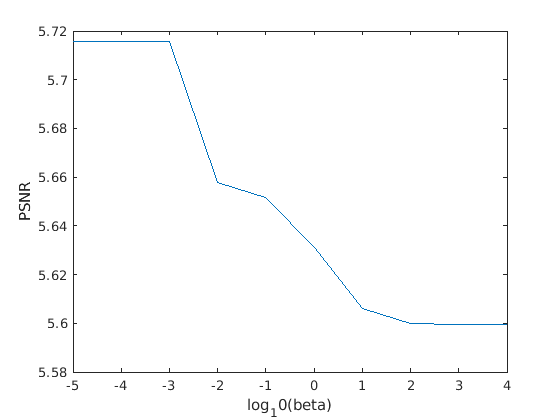

figure
plot(-5:4,list);
xlabel("log_10(beta)");
ylabel("PSNR")

We find that using beta around 1e2 gives a good performance. So now again we do a smaller search between 1e2 and 1e3. The change in PSMR isnt much so we can stop. The opt value is around 400. 

list=zeros(10,1);
epsilon=1e-1;
for i=1:10
    beta=i*10^2;
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
    temp=reshape(y_est,size(org_img));
    list(i)=getPSNR(org_img,temp);
end

Printing the rrmse while breaking the algo    0.0504

Printing the rrmse while breaking the algo    0.0393

Printing the rrmse while breaking the algo    0.0313

Printing the rrmse while breaking the algo    0.0282

Printing the rrmse while breaking the algo    0.0292

Printing the rrmse while breaking the algo    0.0324

Printing the rrmse while breaking the algo    0.0362

Printing the rrmse while breaking the algo    0.0400

Printing the rrmse while breaking the algo    0.0435

Printing the rrmse while breaking the algo    0.0468



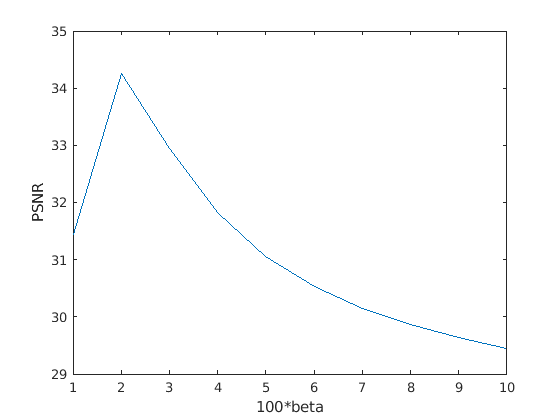

figure
plot(1:10,list);
xlabel("100*beta");
ylabel("PSNR");

We now show the difference it peformance between different epsilon value for the good value of beta

y_est=P4IP(y_col,400,lambda,u_0,v_0,1,size(y));

Printing the rrmse while breaking the algo    0.2959



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   17.6250




y_est=P4IP(y_col,400,lambda,u_0,v_0,0.1,size(y));

Printing the rrmse while breaking the algo    0.0282



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   31.8199




y_est=P4IP(y_col,400,lambda,u_0,v_0,1e-3,size(y));

Printing the rrmse while breaking the algo    0.0199



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   21.6886



variance= var(noise,0,'all');
% Call BM3D With the default settings.
est = BM3D(y, sqrt(variance));
imshow(est);
disp(getPSNR(org_img,est));
%disp(rrmse(org_img,est,2));

y_est=P4IP(y_col,400,lambda,u_0,v_0,0.1,size(y));

Printing the rrmse while breaking the algo    0.0328



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   22.0176



list=zeros(8,1);

for i=1:9
    lambda=10^(i-4);
    y_est=P4IP(y_col,400,lambda,u_0,v_0,0.1,size(y));
    temp=reshape(y_est,size(org_img));
    list(i)=getPSNR(org_img,temp);
end 

Printing the rrmse while breaking the algo    0.0016

Printing the rrmse while breaking the algo    0.0157

Printing the rrmse while breaking the algo    0.0254

Printing the rrmse while breaking the algo    0.0619

Printing the rrmse while breaking the algo    0.0940

Printing the rrmse while breaking the algo    0.0385

Printing the rrmse while breaking the algo    0.0428

Printing the rrmse while breaking the algo    0.0649

Printing the rrmse while breaking the algo    0.0803



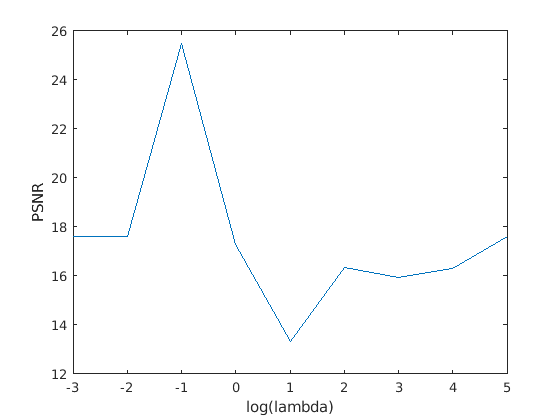

figure
plot(-3:5,list);
xlabel("log(lambda)");
ylabel("PSNR");

Now we come on trying on natural images with poisson noise

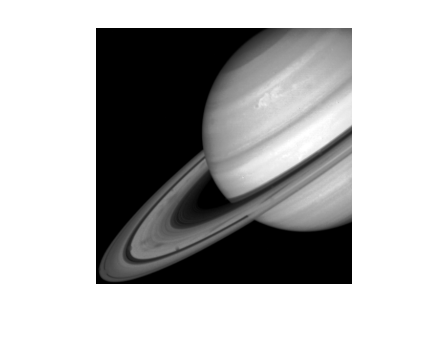

imagename = 'org_sat.png';
org_img = im2double(imread(imagename));
org_img = rgb2gray(org_img);
imagename2 = 'baby.png';
y = im2double(imread(imagename2));
y=rgb2gray(y);
y=y/max(max(y));
imshow(org_img);

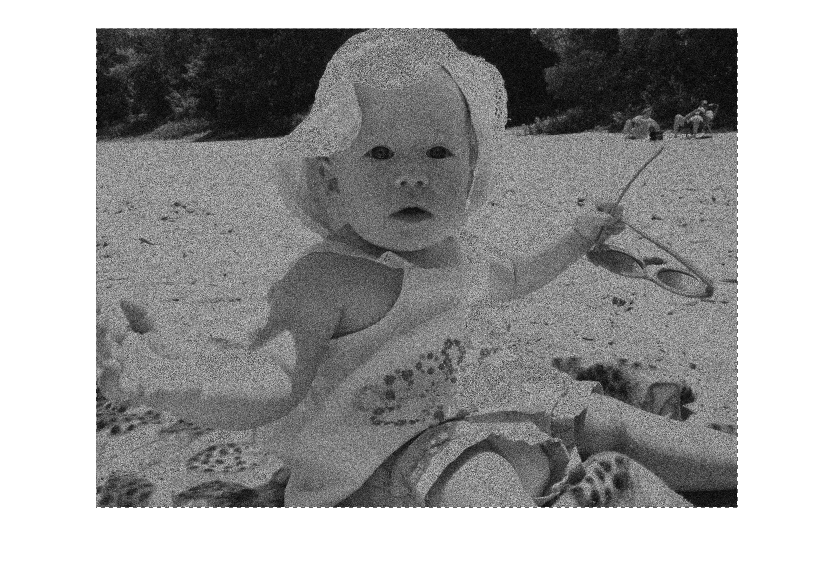

imshow(y);

% disp(getPSNR(org_img,y));
% % y_col = y(:);
% % dim=size(y_col,1);
% % u_0=zeros(dim,1);
% % v_0= y(:);
% % lambda=0.25;

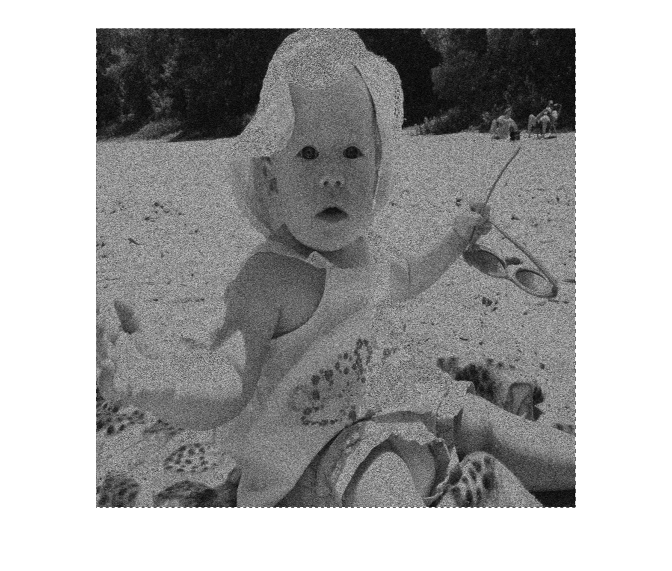

y=imresize(y,[480,480]);
imshow(y);

y=y/max(max(y));

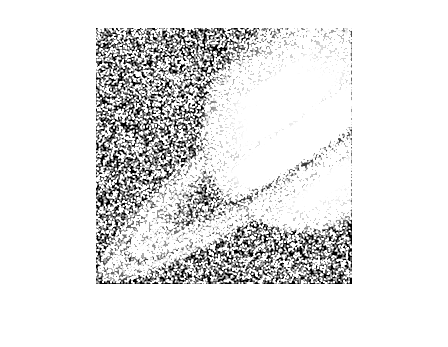

% disp(max(max(y)))
% disp(max(max(org_img)))
temp=conv2(y,ones(2,2)/3,'same');
imshow(temp);

down_siz=1/3;
disp(getPSNR(org_img,temp));

    0.8281



temp1=imresize(temp,down_siz);
disp(size(temp1));

  Column 1

    86

  Column 2

    86



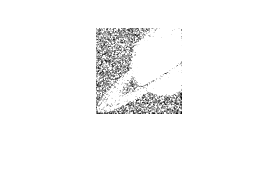

imshow(temp1);

disp(getPSNR(imresize(org_img,down_siz),temp1));

    1.8462



y_col = temp1(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= temp1(:);
lambda=0.25;

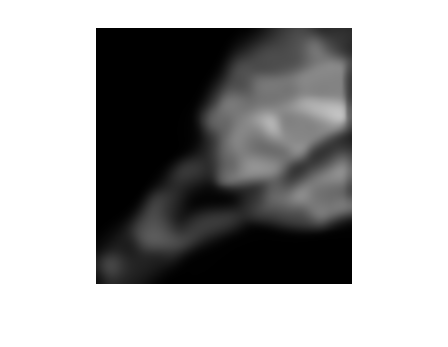

variance= var(temp1,0,'all');
% Call BM3D With the default settings.
est = BM3D(temp1, sqrt(variance));
%est = BM3D(y,2);
imshow(imresize(est,size(org_img)));

disp(getPSNR(imresize(org_img,down_siz),est));

   14.5668



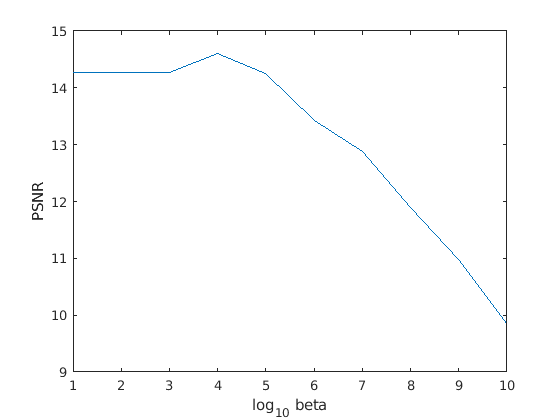

list=zeros(10,1);
epsilon=0.05;
for i=1:10
    beta=10^(i-6);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));
    t=reshape(y_est,size(temp1));
    list(i)=getPSNR(imresize(org_img,down_siz),t);
end
figure
plot(1:10,list);
xlabel("log_{10} beta");
ylabel("PSNR");

list=zeros(10,1);
epsilon=1e-1;
for i=1:10
    beta=i*10^(-3);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));
    t=reshape(y_est,size(temp1));
    list(i)=getPSNR(imresize(org_img,down_siz),t);
end
figure
plot(1:10,list);
xlabel("10^-3 beta");
ylabel("PSNR");

beta=0.008;
epsilon=0.1;
tic
y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(temp1));
toc

Elapsed time is 0.486768 seconds.


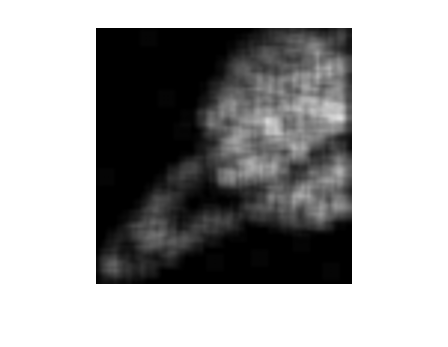

img_est=reshape(y_est,size(temp1));
figure;
imshow(imresize(img_est,size(org_img)));

disp(getPSNR(imresize(org_img,size(down_siz)),img_est))

   12.5676




% img_temp1=deconvlucy(img_temp,ones(4,4)/3,5);
% imshow(img_temp);
% imshow(img_temp1);

img_temp=imresize(img_est,size(org_img));
disp(getPSNR(org_img,img_temp));

noise=poissrnd(0.5,size(org_img));
y=org_img+noise;
disp(max(max(noise)));

     6



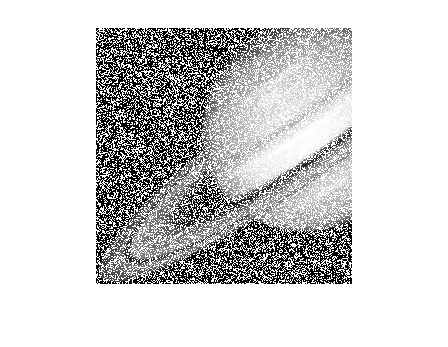

imshow(y)

y_col = y(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= (4*sqrt(3/8)+1)*ones(dim,1);
lambda=0.25;